% Part G - LQG Controller

%Mass of Crane
Mass_Crane= 1000;

% Mass & Cable length of First Load
mass_1= 100; 
length_1= 20; 
% Mass & Cable length of Second Load
mass_2= 100;
length_2= 10;  
% Gravity component
gravity= 9.81; 

%The A and B matrices 

% A matrix
A= [0 1 0 0 0 0; 
    0 0 -(mass_1*gravity)/Mass_Crane 0 -(mass_2*gravity)/Mass_Crane 0;
    0 0 0 1 0 0;
    0 0 -((Mass_Crane+mass_1)*gravity)/(Mass_Crane*length_1) 0 -(mass_2*gravity)/(Mass_Crane*length_1) 0;
    0 0 0 0 0 1;
    0 0 -(mass_1*gravity)/(Mass_Crane*length_2) 0 -(gravity*(Mass_Crane+mass_2))/(Mass_Crane*length_2) 0];

B = [0; 1/Mass_Crane; 0; 1/(Mass_Crane*length_1); 0; 1/(Mass_Crane*length_2)];

% C matrix 
C = eye(6);

% D matrix 
D = zeros(6, 1);

Q = diag([100, 50, 10, 1, 100, 10]);
R = 0.001;

% Observable
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];

D = 0; 

% Initial Conditions for Leunberger observer
x_0 = [0.1 ;0;-0.19;0;0.31;0;0;0;0;0;0;0];


K =lqr(A,B,Q,R);
pro_n=0.28*eye(6);
mes_noise=0.9; 

A_t = A';
C_t = C';
L_0=lqr(A_t,C_t,pro_n,mes_noise); 
L=L_0';

my_system = ss([(A-B*K) B*K; zeros(size(A)) (A-L*C)], [B;zeros(size(B))],[C zeros(size(C))], D);

rng("default")

%Checking the initial response of the closed-loop linear system
init_plot = initialplot(my_system,x_0)


init_plot =

	resppack.simplot



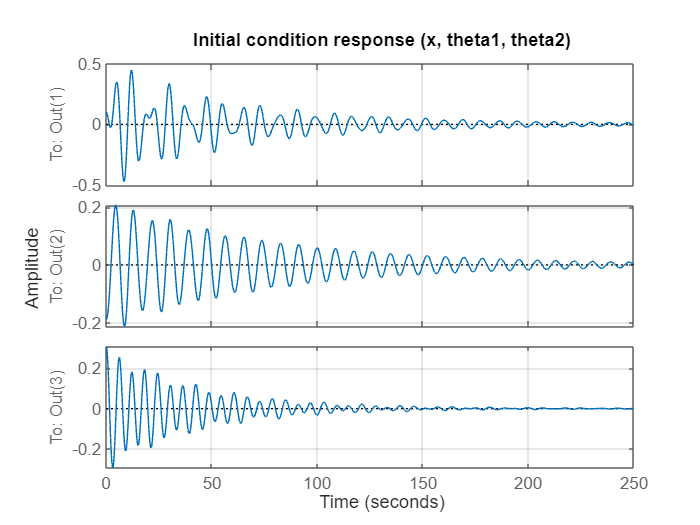

title('Initial condition response (x, theta1, theta2)')

setoptions(init_plot,'TimeUnits','seconds','Grid','on');
setoptions(init_plot, 'XLim',[0 250]);

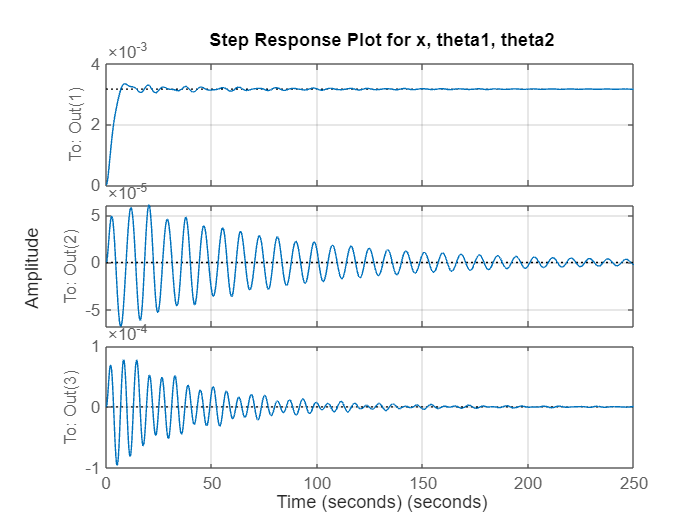



figure
step(my_system);

grid on

% Limit x-axis values to 250 seconds
xlim([0 250])

% Add labels and title for better visualization
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Step Response Plot for x, theta1, theta2')

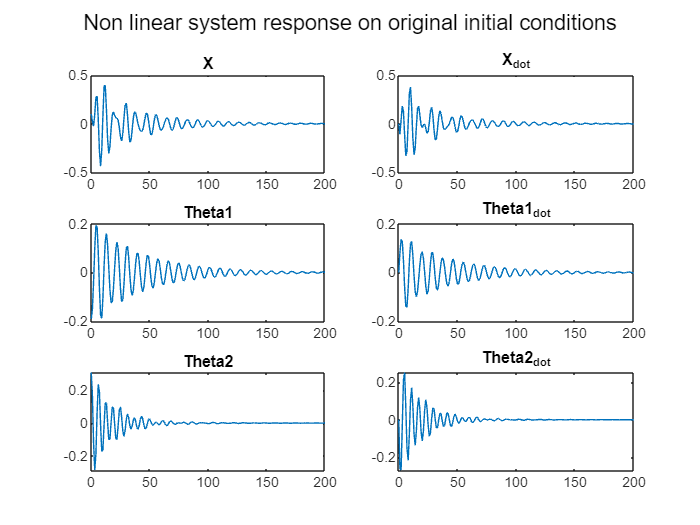

% Non linear

tspan=0:1:200;
[t,x] = ode45(@lqg_slvr,tspan,x_0);
figure;

subplot(3, 2, 1);
plot(t, x(:,1));
title('X');

subplot(3, 2, 2);
plot(t, x(:,2));
title('X_dot');

subplot(3, 2, 3);
plot(t, x(:,3));
title('Theta1');

subplot(3, 2, 4);
plot(t, x(:,4));
title('Theta1_dot');

subplot(3, 2, 5);
plot(t, x(:,5));
title('Theta2');

subplot(3, 2, 6);
plot(t, x(:,6));
title('Theta2_dot');

sgtitle('Non linear system response on original initial conditions');

function diff_eq = lqg_slvr(t,x_ip)
Mass_Crane= 1000;

% Mass & Cable length of First Load
mass_1= 100; 
length_1= 20; 
% Mass & Cable length of Second Load
mass_2= 100;
length_2= 10;  
% Gravity component
gravity= 9.81; 

% A matrix
A= [0 1 0 0 0 0; 
    0 0 -(mass_1*gravity)/Mass_Crane 0 -(mass_2*gravity)/Mass_Crane 0;
    0 0 0 1 0 0;
    0 0 -((Mass_Crane+mass_1)*gravity)/(Mass_Crane*length_1) 0 -(mass_2*gravity)/(Mass_Crane*length_1) 0;
    0 0 0 0 0 1;
    0 0 -(mass_1*gravity)/(Mass_Crane*length_2) 0 -(gravity*(Mass_Crane+mass_2))/(Mass_Crane*length_2) 0];

B = [0; 1/Mass_Crane; 0; 1/(Mass_Crane*length_1); 0; 1/(Mass_Crane*length_2)];

Q = diag([316, 315, 320, 800, 320, 800]);
R = 0.001;



C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; % x , t1 , t2
D = 0;
K = lqr(A,B,Q,R);
u=-K*x_ip(1:6);

s_n=0.29*eye(6);
m_n=0.9;

A_tr = A';
C_tr = C';
L_0=lqr(A_tr,C_tr,s_n,m_n);
L=L_0';


err_terms =(A-L*C)*x_ip(7:12);


diff_eq=zeros(12,1);

diff_eq(1) = x_ip(2);

diff_eq(2)=(u-(gravity/2)*(mass_1*sin(2*x_ip(3))+mass_2*sin(2*x_ip(5)))-(mass_1*length_1*(x_ip(4)^2)*sin(x_ip(3)))-(mass_2*length_2*(x_ip(6)^2)*sin(x_ip(5))))/(Mass_Crane+mass_1*((sin(x_ip(3)))^2)+mass_2*((sin(x_ip(5)))^2));

diff_eq(3)= x_ip(4);

diff_eq(4)= (diff_eq(2)*cos(x_ip(3))-gravity*(sin(x_ip(3))))/length_1';

diff_eq(5)= x_ip(6);

diff_eq(6)= (diff_eq(2)*cos(x_ip(5))-gravity*(sin(x_ip(5))))/length_2;

diff_eq(7)= x_ip(2)-x_ip(10); 

diff_eq(8)= diff_eq(2)-err_terms(2);

diff_eq(9)= x_ip(4)-x_ip(11);

diff_eq(10)= diff_eq(4)-err_terms(4);

diff_eq(11)= x_ip(6)-x_ip(12);

diff_eq(12)= diff_eq(6)-err_terms(6);
end
